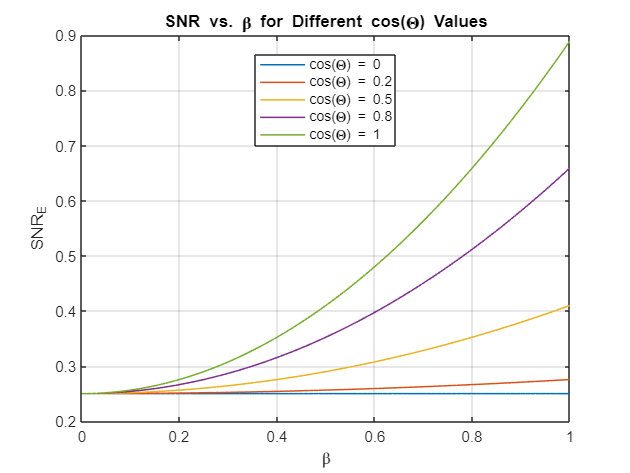

% Define the parameters
rho = 1; % Some value for rho
sigma = 1; % Some value for sigma
h_BE = 0.5; % Channel coefficient h_BE
h_BI = 0.8; % Channel coefficient h_BI
beta_values = linspace(0, 1, 100); % Range of beta values (0 to 1)
theta_values = [0, 0.2, 0.5, 0.8, 1]; % Different values of cos(theta)

% Initialize a figure
figure;

% Plot SNR vs. beta for different cos(theta) values
for i = 1:length(theta_values)
    cos_theta = theta_values(i);
    SNR_E = (abs(h_BE)^2 * rho + abs(beta_values .* h_BI).^2 * rho * cos_theta^2) / sigma;
    
    % Plot current line with different color
    plot(beta_values, SNR_E, 'LineWidth', 1, 'DisplayName', ['cos(\Theta) = ' num2str(cos_theta)]);
    hold on;
end

xlabel('\beta');
ylabel('SNR_E');
title('SNR vs. \beta for Different cos(\Theta) Values');
legend('Location', 'Best');
grid on;
hold off;